video = VideoReader("sea-turtle.mp4")

video =   VideoReader with properties:

   General Properties:
            Name: 'sea-turtle.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Sea-Turtle'
        Duration: 7.3600
     CurrentTime: 0.0400
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 1802
          Height: 1202
       FrameRate: 25
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



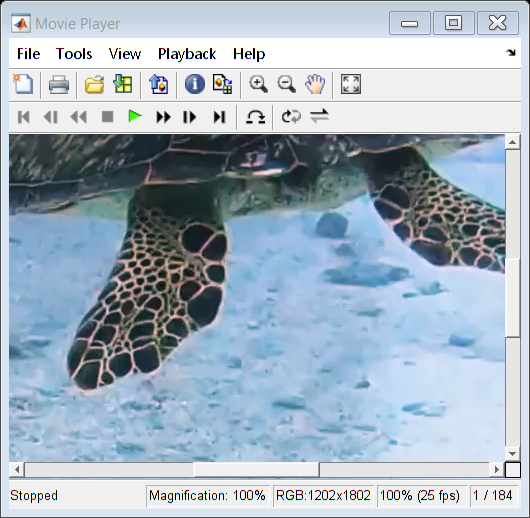

implay("sea-turtle.mp4")

I = read(video,100);
[maskTurtle,maskedRGBImage] = createMaskTurtle(I);

numFrames_turtle= video.NumFrames;
v_seg= VideoWriter("boxed-turtle","MPEG-4");

v_seg.FrameRate = video.FrameRate;
v_seg_comb.FrameRate = video.FrameRate;
%open(v_seg);
bboxes = [];
idxes = [];
for i = 1 : 70
    frame = read(video,i);

    [maskTurtle,maskedRGBImage] = createMaskTurtle(frame);
    [BW,maskedImage] = segmentImageTurtle(maskedRGBImage);
    BW = filterRegions1stPart(BW);
    props = regionprops("table",BW,"BoundingBox");
    BoxedTurtle =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    %writeVideo(v_seg, BoxedTurtle);
    bboxes = [bboxes;props];
    idxes = [idxes;i];
end
%close(v_seg);

coords=[];
coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords);
writetable(coords,"coords.txt");

open(v_seg);

for i = 71 : numFrames_turtle
    frame = read(video,i);

    [maskTurtle,maskedRGBImage] = createMaskTurtle(frame);
    [BW,maskedImage] = segmentImageTutrlefrom70(maskedRGBImage);
    BW = filterRegions1stPart(BW);
    props = regionprops("table",BW,"BoundingBox");
    BoxedTurtle =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    writeVideo(v_seg, BoxedTurtle);

end
close(v_seg);

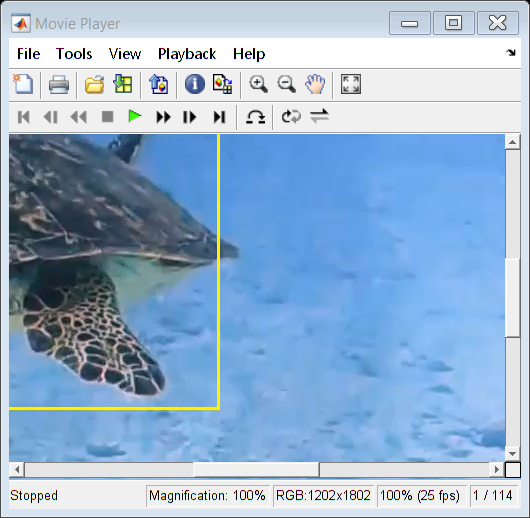

implay("boxed-turtle.mp4")